mu=0.004; %blood viscosity
pIn=7000; %artery border condition
pOut=2000; %venous border condition
el=3000;% Elasticity

vesselsN=148;
nodesN=98;
vesselEq=0;
nodeEq=1;

tspan = [0 100];
tspan


for i=1:1:(nodesN*nodeEq+vesselsN*vesselEq)
   yzero(1,i)=1; 
end
yzero

%%
yzero = ones(1,nodesN*nodeEq+vesselsN*vesselEq)
%%

syms x
limit((x^3 + 5)/(x^4 + 7))


% function dydt = odefun(t,y)
% dydt = 5*y-3;
% end

X = [1 0 2; 0 1 1; 0 0 4]
find_res = find(X,5,'first')
find(X,3,'last')

f = @(x,y) (x.^2 - y.^2);


f(3,2) == feval(f,3,2)

x = 0.1

ones(2) * ones(2)

ans =      2     2
     2     2


ones(2) .* ones(2)

ans =      1     1
     1     1


ones(2) * ones(2,1)

ans =      2
     2


ones(2) .* ones(2,1) % this is still ok

ans =      1     1
     1     1


ones(2) .* 2 % this is still ok

ans =      2     2
     2     2


ones(2) * 2 % this is still ok

ans =      2     2
     2     2



ones(2) .* ones(3,1)

Matrix dimensions must agree.

使用 `ode23` 对区间 [0,3] 内初始条件为 `y0 = 0` 的简单 ODE `y' = t^2` 求解。

其实simply  y = 1/3*t^3

sol = ode23(@(t,y) t^2, [0 3], 0);
x = linspace(0,3,7);
[y,yp] = deval(sol,x)

y =          0    0.0417    0.3333    1.1250    2.6667    5.2083    9.0000


yp =          0    0.2500    1.0000    2.2500    4.0000    6.2500    9.0000


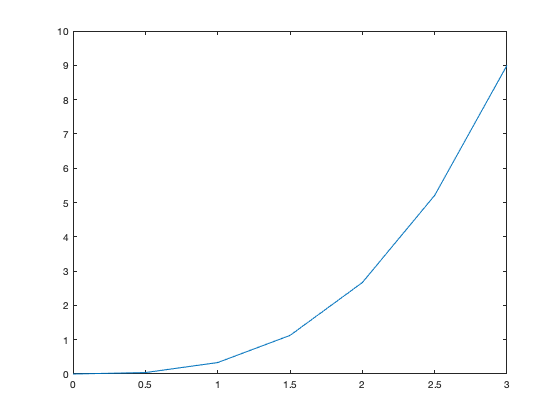

ans = 0.0417

plot(x,y)

y =          0
   -0.3578
   -2.1466
   -4.1466
   -6.1466
   -8.1466
  -10.1466
  -12.1466
  -14.1466
  -16.1466


tspan = [0 2];
y0 = 1;
[t,y] = ode23s(@(t,y) -10*t, tspan, y0);

f = @(t,y)(y-10*t)

f = function_handle with value:
    @(t,y)(y-10*t)



[t,y] = ode23s(f, tspan, y0);

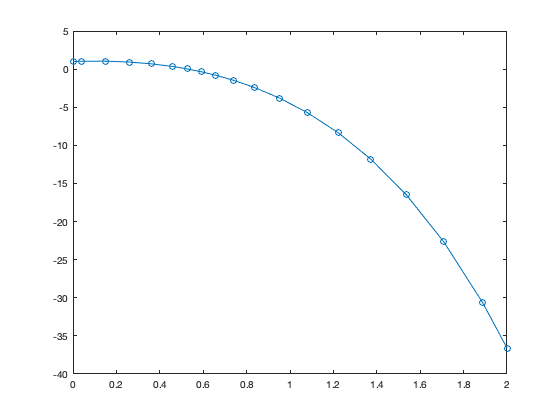

plot(t,y,'-o')

vdp1000

Not enough input arguments.

Error in vdp1000 (line 9)
dydt = [y(2); 1000*(1-y(1)^2)*y(2)-y(1)];

s = 0

s = 0

s(3) = 1

s =      0     0     1


function_def(1,2)

ans = 3

max(aaFull)

ans = 311.9300

min(aaFull)

ans = 0

(max(aaFull)-min(aaFull))/20

ans = 15.5965

x(2) - x(1)

ans = 15.5965

[f,x]= hist(aaFull',20);
pd=fitdist(aaFull,'Exponential');
res=1/pd.mu*exp(-(0:1:500)/pd.mu);
res_pdf = pdf(pd,(0:1:500))

res_pdf =     0.0189    0.0185    0.0182    0.0179    0.0175    0.0172    0.0169    0.0166    0.0162    0.0159    0.0156    0.0154    0.0151    0.0148    0.0145    0.0142    0.0140    0.0137    0.0135    0.0132    0.0130    0.0127    0.0125    0.0122    0.0120    0.0118    0.0116    0.0113    0.0111    0.0109    0.0107    0.0105    0.0103    0.0101    0.0099    0.0098    0.0096    0.0094    0.0092    0.0090    0.0089    0.0087    0.0085    0.0084    0.0082    0.0081    0.0079    0.0078    0.0076    0.0075


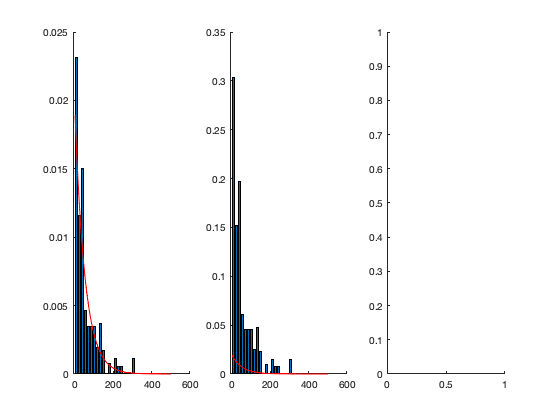

%mu of clraity*0.8= 42.325850369432885

figure
subplot(1,3,1)
hold on
bar(x,f/trapz(x,f));
plot((0:1:500),res,'r');
%plot((0:1:500),res_pdf,'b');

hold off

subplot(1,3,2)
hold on
bar(x,f/sum(f));
plot((0:1:500),res_pdf,'r');
hold off

subplot(1,3,3)


image(clarity)

Unrecognized function or variable 'clarity'.

Y = [1 4 9 16 25];
Q = trapz(Y)

Q = 42

`Y` contains function values for *f*(*x*)=*x*2 in the domain [1, 5].

Use `trapz` to integrate the data with unit spacing.

    function yPrime=model(t,y)
        for k=1:1:nephronsN
            cur=0;
            cnidx = find ( (nodesMatrix(:,9) == nephronsMatrix(k,1) | nodesMatrix(:,10) == nephronsMatrix(k,1) ), 1, 'first');
            cvidx = find ( (vesselsMatrix(:,1) == nephronsMatrix(k,1)), 1, 'first');
            
            if k==number
                cur=current;
            end
            yPrime(k,1)=cur+(y(nephronsN+cnidx)-y(k))/electricalResistance(cvidx) - y(k)/R_neph;
            
        end
        previousEq=nephronsN;
        for k=1:1:nodesN
            cn1idx = find (nodesMatrix(:,1) == nodesMatrix(k,3), 1, 'first');
            cn2idx = find (nodesMatrix(:,1) == nodesMatrix(k,4), 1, 'first');
            cn3idx = find (nodesMatrix(:,1) == nodesMatrix(k,5), 1, 'first');
            
            cv1idx = find (vesselsMatrix(:,1) == nodesMatrix(k,6), 1, 'first');
            cv2idx = find (vesselsMatrix(:,1) == nodesMatrix(k,7),1, 'first');
            cv3idx = find (vesselsMatrix(:,1) == nodesMatrix(k,8),1, 'first');
            
            
            if (nodesMatrix (k,3)==-1)
                cpsi1=y(previousEq+k);
            else
                cpsi1=y(previousEq+cn1idx);
            end
            if (nodesMatrix (k,4)==-1)
                cneph1idx = find (nephronsMatrix(:,1) == nodesMatrix(k,9), 1, 'first');
                cpsi2=y(cneph1idx);
            else
                cpsi2=y(previousEq+cn2idx);
            end
            if (nodesMatrix (k,5)==-1)
                cneph2idx = find (nephronsMatrix(:,1) == nodesMatrix(k,10), 1, 'first');
                cpsi3=y(cneph2idx);
            else
                cpsi3=y(previousEq+cn3idx);
            end
                                   
            yPrime (previousEq+k,1) =(cpsi1-y(previousEq+k))/electricalResistance(cv1idx)+(cpsi2-y(previousEq+k))/electricalResistance(cv2idx)+(cpsi3-y(previousEq+k))/electricalResistance(cv3idx) - y(previousEq+k)/R_leak;
            
        end
    end